# **TU: Linear Regression**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Fit Linear Regression

## Include path

addpath('../../Library')  

# Examples

## Example 1: Fit with Linear Regression 

### **Data Acquisition**

- Feature: One-Dimension,  p=1

- True value: ytrue = 2X+3

x = randn(100,1);
y = x*2 + 3+randn(100,1);

### **Fit Linear Regression**

mdl = fitlm(x,y)

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     2.9193       0.1013    28.819    1.1939e-49
    x1              2.0652     0.087093    23.713    2.1985e-42


관측값 개수: 100, 오차 자유도: 98
RMS 오차: 1.01
결정계수: 0.852, 수정된 결정계수: 0.85
상수 모델에 대한 F-통계량: 562, p-값 = 2.2e-42

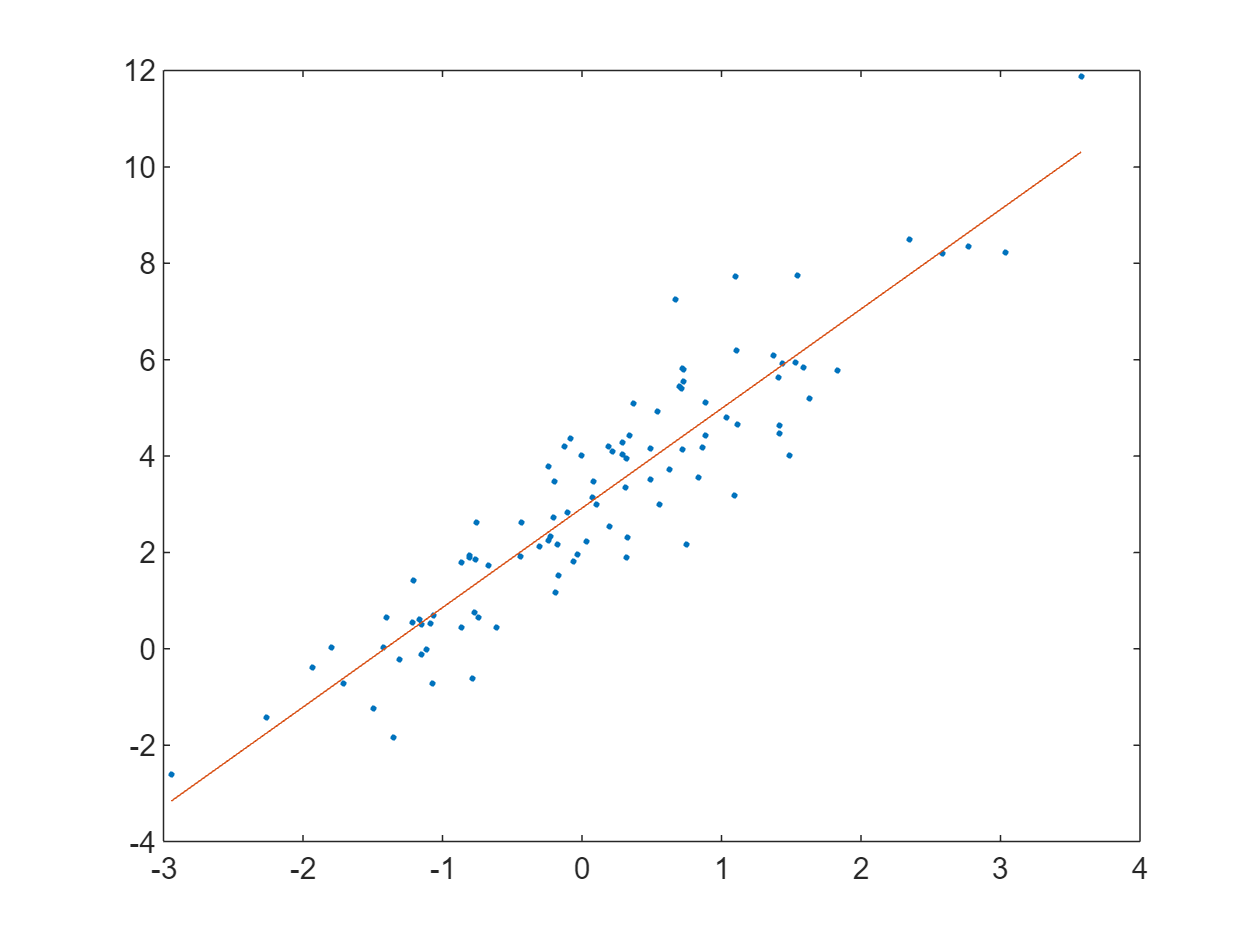


% Plot prediction
plot(x,y,'.',x,mdl.Fitted, '-')

### **Analyze Linear Regression**

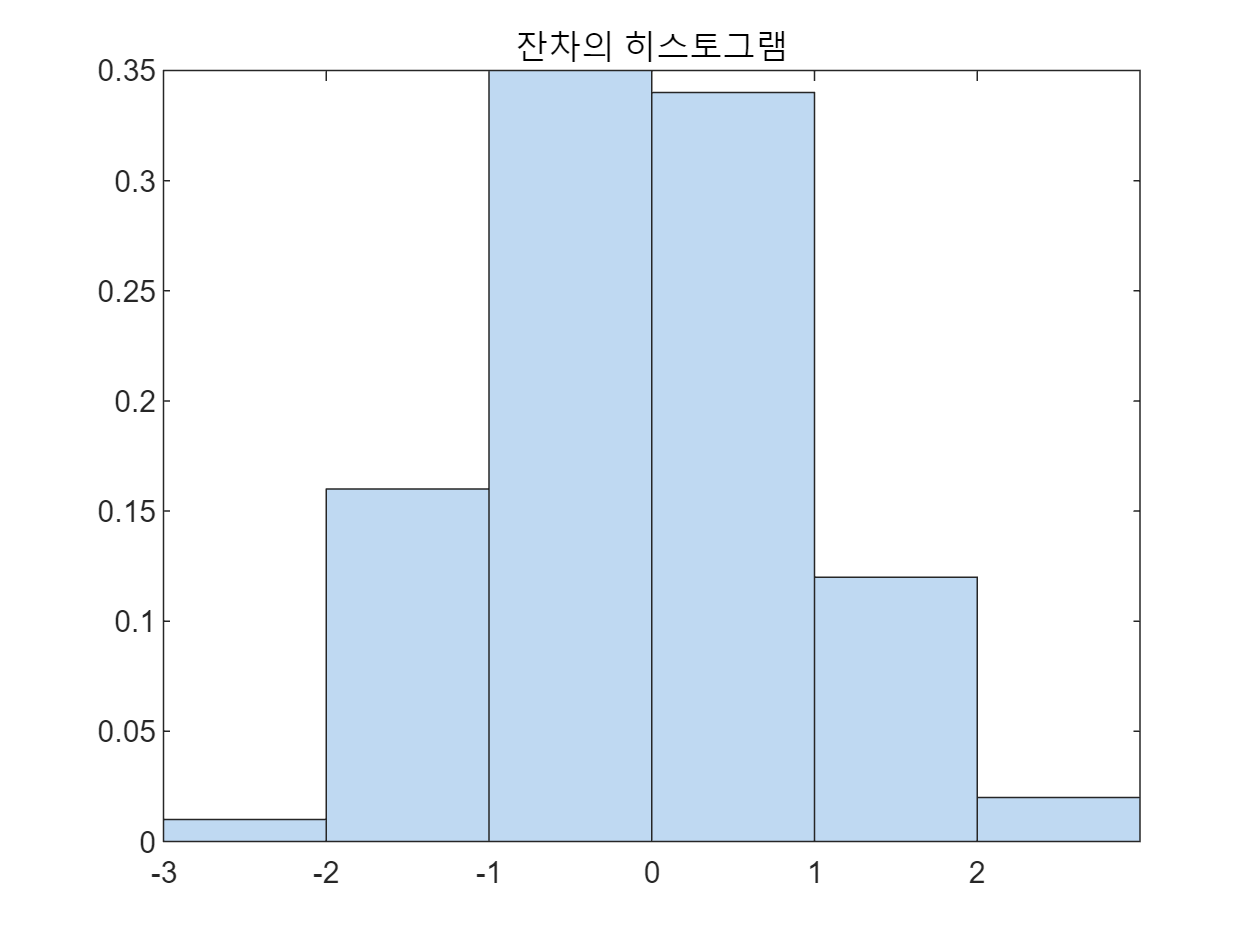

% Plot residual histogram
plotResiduals(mdl)


% From remove outlier from histogram
outl = find(abs(mdl.Residuals.Raw) > 2);
mdl.Residuals.Raw(outl)

ans =     2.9449
    2.5349
   -2.2979



% Fit with outlier removed
mdl2 = fitlm(x,y,'Exclude',outl)

mdl2 = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     2.8886     0.092874    31.102    1.3369e-51
    x1              2.0446     0.079297    25.784    1.1196e-44


관측값 개수: 97, 오차 자유도: 95
RMS 오차: 0.911
결정계수: 0.875, 수정된 결정계수: 0.874
상수 모델에 대한 F-통계량: 665, p-값 = 1.12e-44

### **Predict with Test data**

% Ypredict and confidence interval
Xnew=2;
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 6.9777

YnewI =     6.6268    7.3286


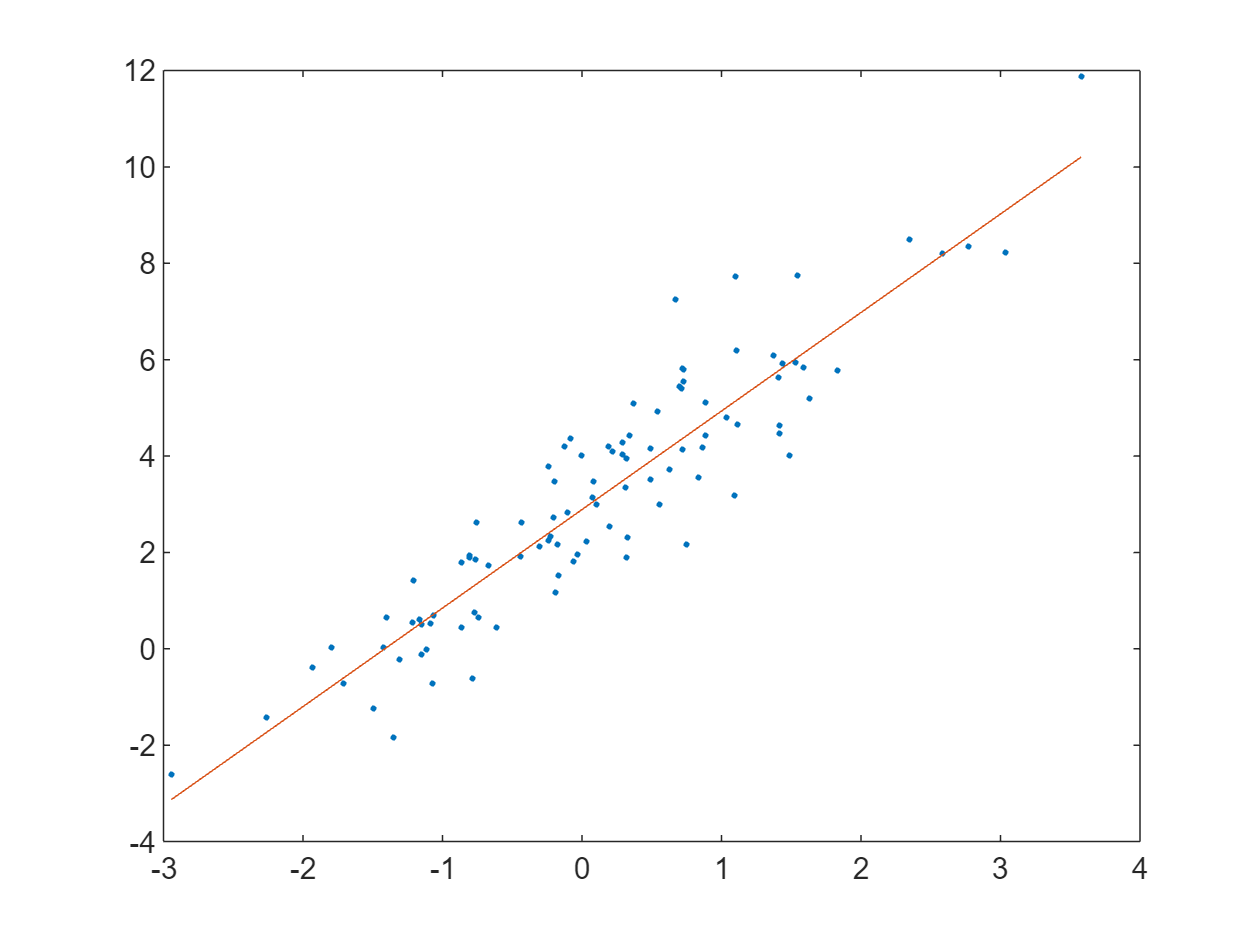


% Plot prediction
plot(x,y,'.',x,mdl2.Fitted, '-')

## Example 2: Predict Car MPG

Find linear relationship of  MPG(연비) with   Weight & Displacement

Then, Predict MPG for a car with Weight=3000 , Displacement=300

### **Data Acquisition**

-  Dependet Variable:  MPG

- Independet Variables: Weight, Displacement

clear
load carsmall

tbl = table(MPG,Weight, Displacement);  % table type

### **Fit  Linear Regression**

mdl = fitlm(tbl,'MPG~Weight+Displacement')

mdl = 선형 회귀 모델:
    MPG ~ 1 + Weight + Displacement

추정된 계수:
                     Estimate        SE         tStat       pValue  
                    __________    _________    _______    __________

    (Intercept)         46.925       2.0858     22.497    6.0509e-39
    Weight          -0.0068422    0.0011337    -6.0353    3.3838e-08
    Displacement     -0.014593    0.0082695    -1.7647      0.080968


관측값 개수: 94, 오차 자유도: 91
RMS 오차: 4.09
결정계수: 0.747, 수정된 결정계수: 0.741
상수 모델에 대한 F-통계량: 134, p-값 = 7.22e-28

mdl.CoefficientNames

ans = 1×3 cell 배열
    {'(Intercept)'}    {'Weight'}    {'Displacement'}


mdl.Coefficients.Estimate

ans =    46.9247
   -0.0068
   -0.0146


### **Analyze Linear Regression**

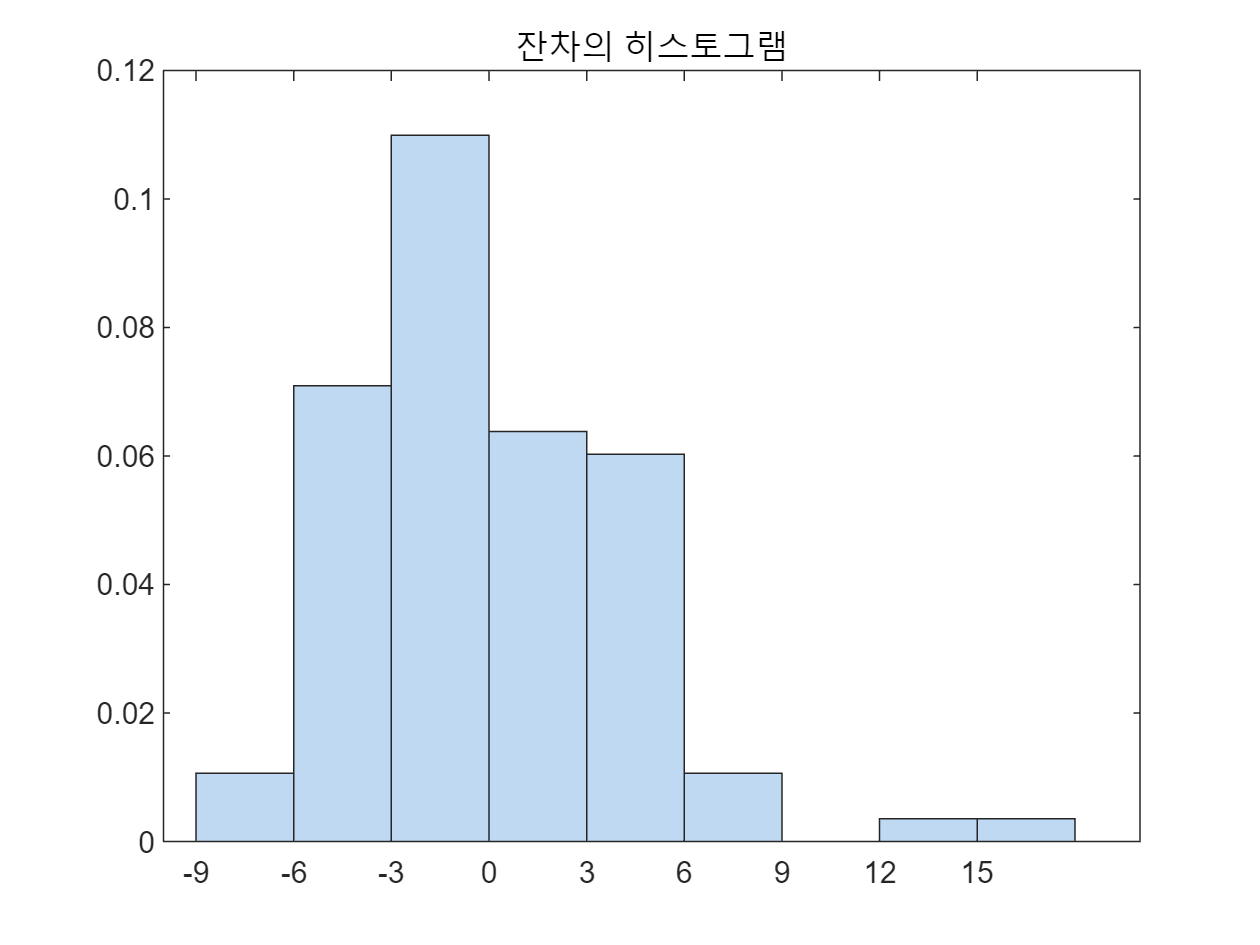

plotResiduals(mdl)


% Remove outlier
outl = find((mdl.Residuals.Raw) > 9);

% Fit with outlier removed
mdl2 = fitlm(tbl,'MPG~Weight+Displacement','Exclude',outl)

mdl2 = 선형 회귀 모델:
    MPG ~ 1 + Weight + Displacement

추정된 계수:
                     Estimate         SE         tStat       pValue  
                    __________    __________    _______    __________

    (Intercept)         45.548        1.8056     25.226    2.5559e-42
    Weight          -0.0062503    0.00097845    -6.3879    7.4767e-09
    Displacement     -0.018035     0.0071414    -2.5255      0.013324


관측값 개수: 92, 오차 자유도: 89
RMS 오차: 3.51
결정계수: 0.796, 수정된 결정계수: 0.792
상수 모델에 대한 F-통계량: 174, p-값 = 1.78e-31

mdl2.Coefficients.Estimate

ans =    45.5477
   -0.0063
   -0.0180


### **Predict**

Detailed look at the interactions 

% Ypredict and confidence interval
Xnew=[3000 300]; 
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 21.3863

YnewI =    19.8515   22.9211


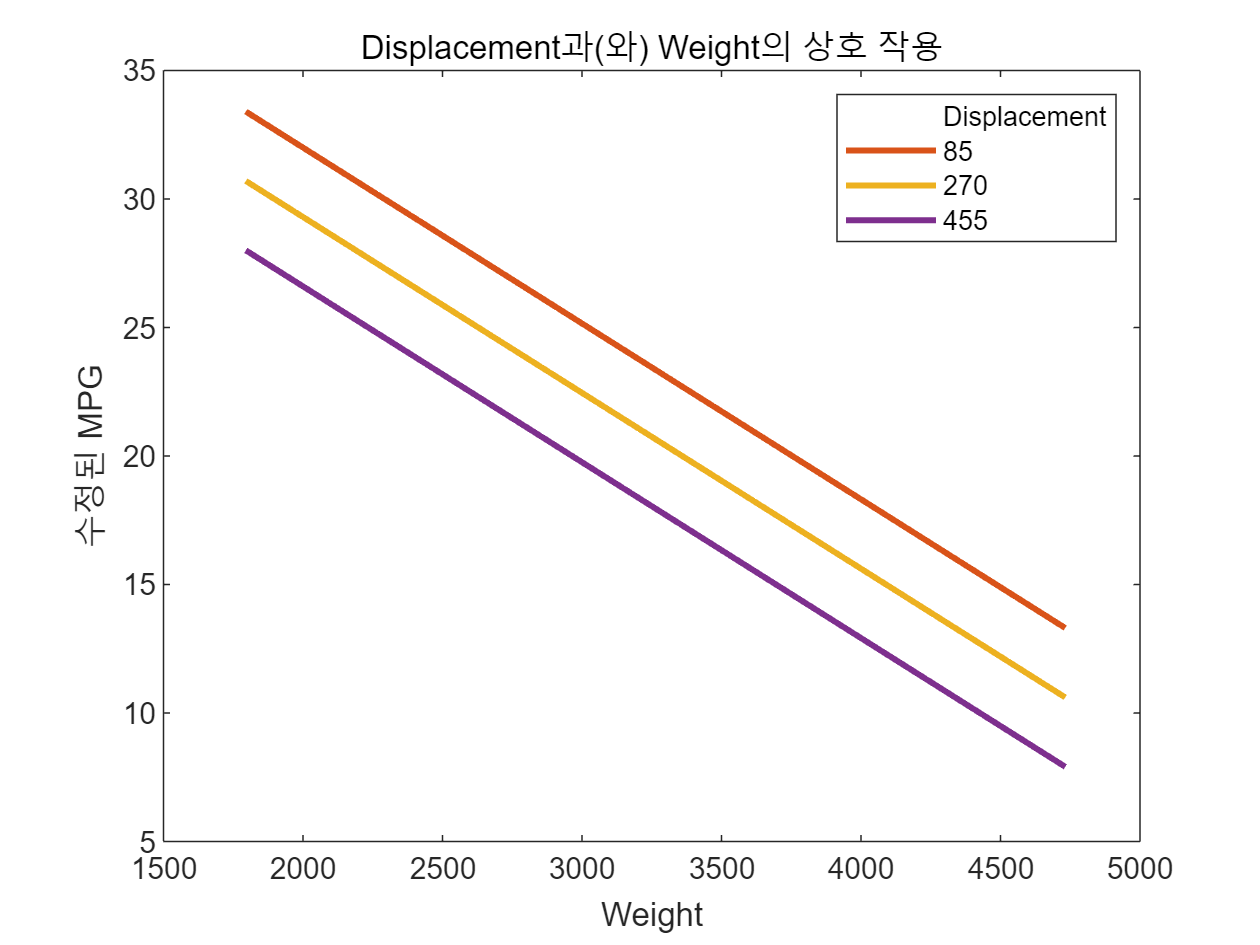


plotInteraction(mdl,'Displacement','Weight','predictions')

# Exercise

## Exercise 1 :  Gradient Descent

**Linear Regression Using Gradient Descent**

Hypothesis. 

To find the parameters, repeat until convergence

where, cost(error) function

and

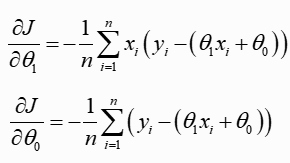

### **Data Acquisition**

Feature: One-Dimension,  p=1

True: y = 2X+3

N=100;
X = randn(N,1);
Y = X*2 + 3+randn(N,1);



### **Fit Linear Regression:  Gradient Descent**

% dJ/dx
lamda=0.1;  % learning rate

% Initialization for t0, t1
t0=0.5;
t1=0.5;
loss=1;
itrN=1000;
k=1;

t1_prev=0;
t0_prev=0;

%% ADD your code here
while(loss>0.0001 && k<itrN)
    
    % Define function h(x)
    % h=_____________;
    
    % Define gradient w.r.t theta_1 and theta_0
    % dJt1 = __________;
    % dJt0 = __________;
    
    % Update theta1, theta0
    % t1=________;
    % t0=________;

    % Cost Function v1      
    % loss=sum((Y-h).^2)/(2*N);
    
    % Cost Function v2      
    loss= (norm(t1-t1_prev)+norm(t0-t0_prev))/2;
    t1_prev=t1;
    t0_prev=t0;

    loss_hist(k) = loss;
    k=k+1;
end


% Plot loss vs iteration
figure
plot(loss_hist)


% Predicted hypothesis y(x)
% ypred=___________ %%% ADD your code here

disp('optimal paraterms are')

optimal paraterms are


t1

t1 = 2.0370

t0

t0 = 2.9394


% MATLAB fit linear using fitlm(x,y)
% mdl = ____________   %%% ADD your code here

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     2.9394     0.095168    30.886    2.6197e-52
    x1               2.037     0.093552    21.774    2.5017e-39


관측값 개수: 100, 오차 자유도: 98
RMS 오차: 0.946
결정계수: 0.829, 수정된 결정계수: 0.827
상수 모델에 대한 F-통계량: 474, p-값 = 2.5e-39

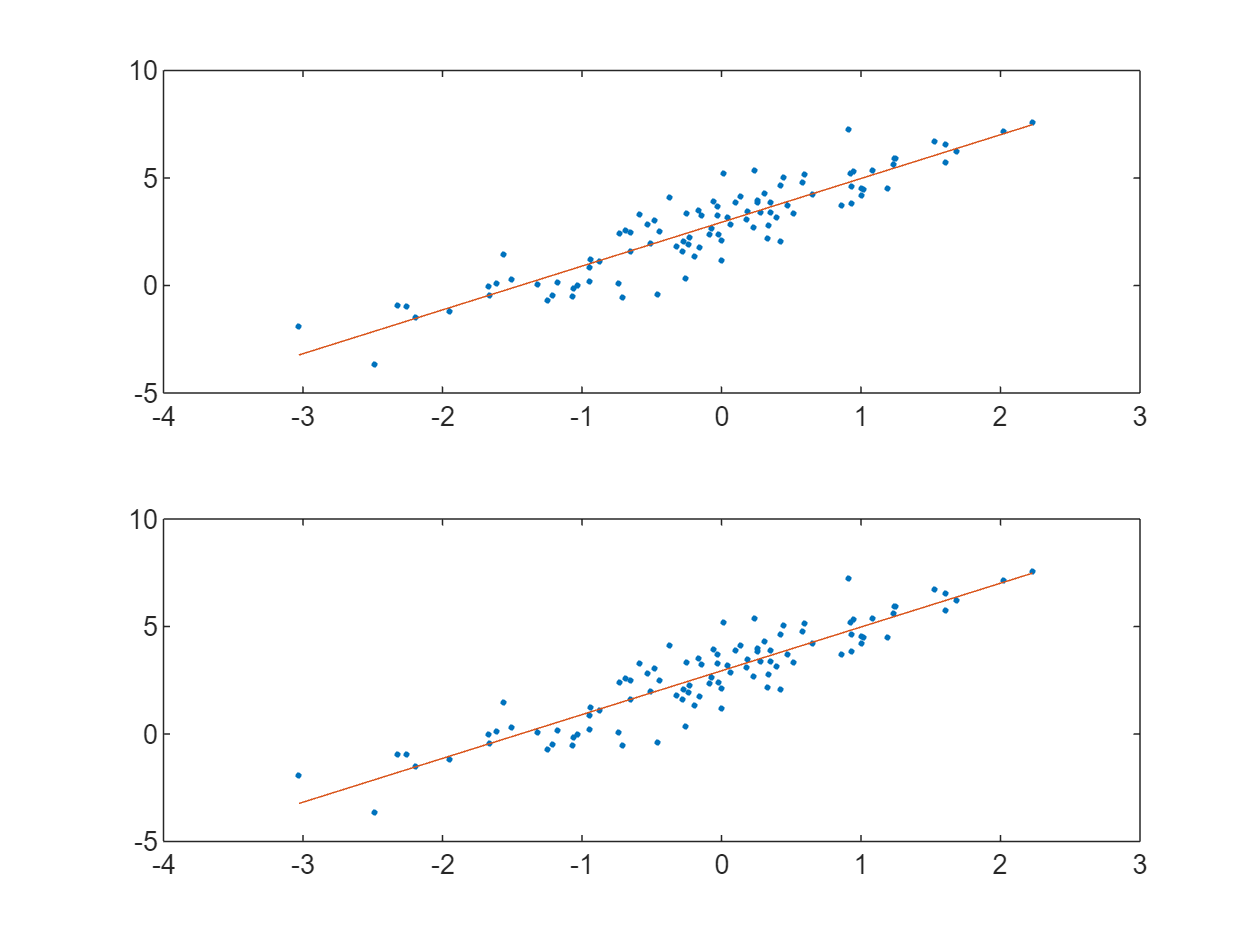



% Plot and compare predictions
figure
subplot(2,1,1)
plot(X,Y,'.',X,mdl.Fitted, '-')
subplot(2,1,2)
plot(X,Y,'.',X,ypred, '-')

## Exercise 2 :  Linear Regression with dim=2

Find the linear regression. Remove Outlier and predict a test value Xtest=[2;1];.  You can use MATLAB fitlm()

- Feature: 2-Dimensions,  p=2

- True value: y = 2*X1+4*X2+3

### **Data Acquisition**

X = randn(100,2);
y = X*[2;4] + 3+ randn(100,1);

### **Fit  Linear Regression**

% mdl=____________   
% Your code goes here

### **Analyze**

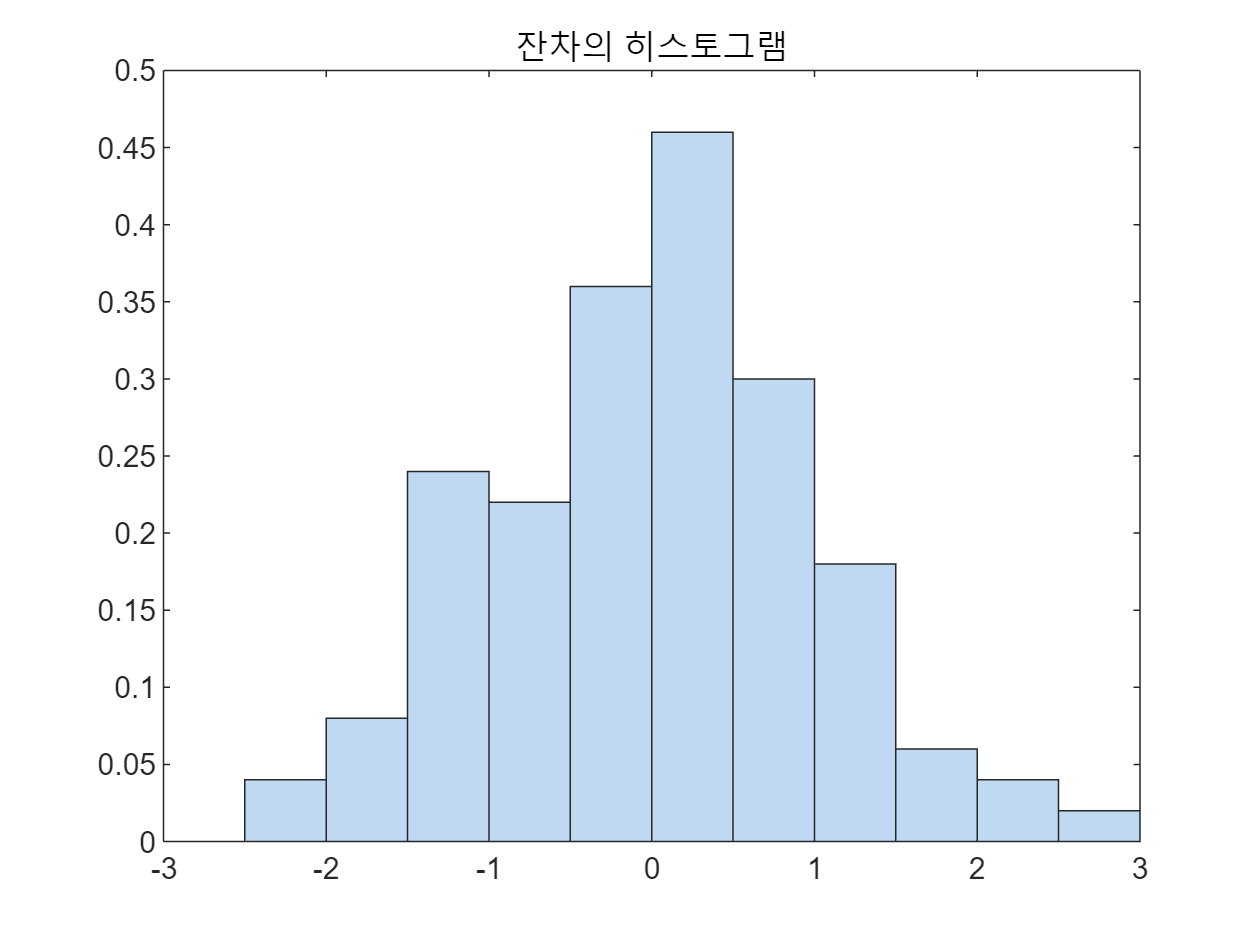

% Remove outlier
%  -plot residual histogram
figure
plotResiduals(mdl)

% - remove outlier from histogram analysis
% outl =________________;



% Fit linear regression (fitlm)
% mdl2 = ______________________;

% Your code goes here


### **Predict**

Predict for a Test value

Xnew=[2, 1];

ans =     2.0944
   -2.0598
    2.0142
   -2.2797
    2.5725


% Ynew=___________

mdl2 = 선형 회귀 모델:
    y ~ 1 + x1 + x2

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     2.9436     0.087075    33.806    1.1366e-53
    x1              2.0996      0.10268    20.448      5.52e-36
    x2              3.9035     0.089767    43.484    3.8667e-63


관측값 개수: 95, 오차 자유도: 92
RMS 오차: 0.848
결정계수: 0.962, 수정된 결정계수: 0.961
상수 모델에 대한 F-통계량: 1.17e+03, p-값 = 3.33e-66

% Your code goes here


## Exercise 3:  Linear Regression with dim=4

Find linear relationship of 

- MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight 

Choose a test data and predict

### **Data Acquisition**

clear
load carsmall

tbl = table(MPG,Acceleration,Displacement,Horsepower,Weight);

Ynew = 11.0462

YnewI =    10.5737   11.5188


### **Fit  Linear Regression**

mdl = fitlm(tbl, 'MPG~Acceleration+Displacement+Horsepower+Weight')

### **Analyze**

% Remove outlier
%  -plot residual histogram
% - remove outlier from histogram analysis
% outl =________________;


mdl = 선형 회귀 모델:
    MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight

추정된 계수:
                     Estimate        SE         tStat        pValue  
                    __________    _________    ________    __________

    (Intercept)         48.117       3.9008      12.335    6.9194e-21
    Acceleration     -0.060312      0.21167    -0.28493       0.77636
    Displacement    -0.0066826     0.011594    -0.57638       0.56583
    Horsepower       -0.037547     0.026139     -1.4364       0.15442
    Weight           -0.006084    0.0013823     -4.4014      3.01e-05


관측값 개수: 93, 오차 자유도: 88
RMS 오차: 4.11
결정계수: 0.753, 수정된 결정계수: 0.742
상수 모델에 대한 F-통계량: 67.1, p-값 = 6.49e-26


% Fit linear regression (fitlm)
% mdl2 = ______________________;

% Your code goes here




### **Predict**

Predict for a Test value

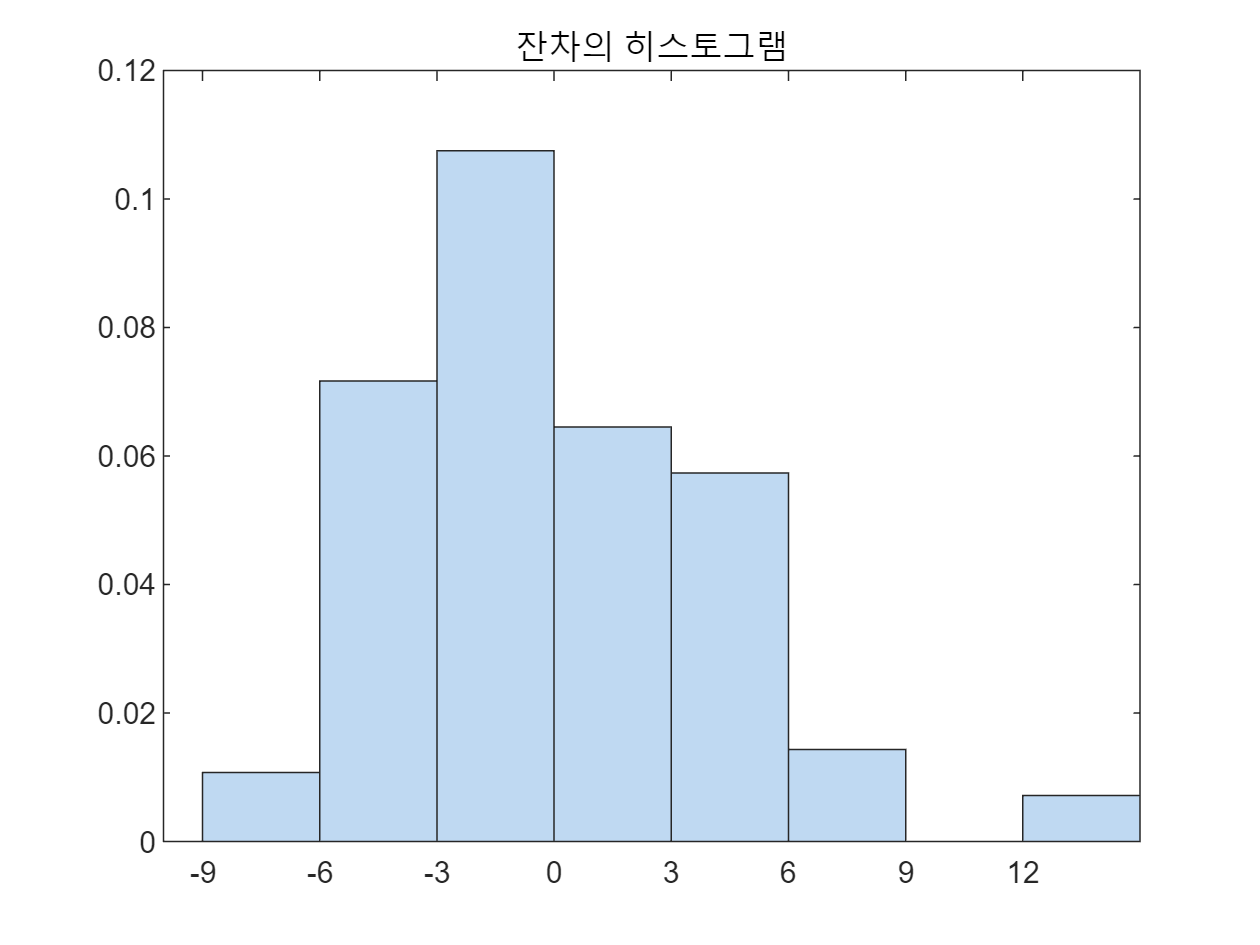

Xnew = [10 300 150 3500];

% Ynew=___________
% Your code goes here

mdl2 = 선형 회귀 모델:
    MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight

추정된 계수:
                     Estimate        SE         tStat       pValue  
                    __________    _________    _______    __________

    (Intercept)         52.278       3.4049     15.354    2.2896e-26
    Acceleration      -0.44717      0.19284    -2.3189      0.022774
    Displacement     -0.027687     0.010354     -2.674      0.008968
    Horsepower       -0.023844     0.022474    -1.0609       0.29169
    Weight          -0.0047039    0.0011924    -3.9449    0.00016242


관측값 개수: 91, 오차 자유도: 86
RMS 오차: 3.46
결정계수: 0.809, 수정된 결정계수: 0.8
상수 모델에 대한 F-통계량: 90.8, p-값 = 4.83e-30

Ynew = 19.4598

YnewI =    18.0114   20.9082
